clear all 

close all 

# BE Systèmes Multidimensionnels

#### Définition du système pour 6 noeuds

L'objectif de ce BE est de synthétiser une commande insensible et découplé pour commander les angles de proue et de poupe pour un sous marin.

## 1) Analysis of the natural system.

1) Nous avons tout d'abord commencé par utiliser les données de l'énoncé pour représenter notre système sous forme d'une représentation d'état. Nous avons donc choisi de continuer la suite de ce bureau d'étude avec le système du sous-marin se déplaçant à une vitesse de 6 noeuds.


% Matrices du système à une vitesse de 6 nœuds
A_6 = [-0.038006, 0.89604, 0, 0.0014673;
        0.0017105, -0.091676, 0, -0.0056095;
        1, 0, 0, -3.0867;
        0, 1, 0, 0];

B_6 = [-0.007542, -0.022859;
        0.0017323, -0.0022217;
        0, 0;
        0, 0];


C_6 = [0, 0, 1, 0;
     0, 0, 0, 1];

D_6=zeros(2,2);



Représentation d'état:

% Système pour 6 noeuds
sys_6K=ss(A_6,B_6,C_6,D_6);

2) Nous avons par la suite souhaité observer la commandabilité et l'observabilité de notre système "sys_6K". Pour ce faire, nous avons utilisé les fonctions Matlab "rank()", qui nous permettent d'obtenir le rang de la matrice d'évolution de contrôlabilité et de la matrice d'observabilité.

Commandabilité du système

Co_6 = ctrb(A_6, B_6);     % Calcul de la matrice de commandabilité
rang_comm_6 = rank(Co_6);

if rang_comm_6 == size(A_6, 1)
    disp('Le système à 6 nœuds est commandable.');
else
    disp('Le système à 6 nœuds n est pas commandable.');
end

Le système à 6 nœuds est commandable.


On observe que le rang de la matrice de commandabilité est bien équivalent au rang de la matrice d'évolution, le sous-marin lorsqu'il se déplace à 6 noeuds est donc bien commandable.

Observabilité du système

Ob_6 = obsv(A_6, C_6);     % Calcul de la matrice d'observabilité
rang_observ_6 = rank(Ob_6);

if rang_observ_6 == size(A_6, 1)
    disp('Le système à 6 nœuds est observable.');
else
    disp('Le système à 6 nœuds n est pas observable.');
end

Le système à 6 nœuds est observable.


On observe que le rang de la matrice d'observabilité est bien équivalent au rang de la matrice d'évolution, le sous-marin lorsqu'il se déplace à 6 noeuds est donc bien commandable.

3) Nous avons ensuite souhaité afficher les pôles de notre système dans le plan de Laplace (plan complexe) 

Affichage des pôles dans le plan de Laplace

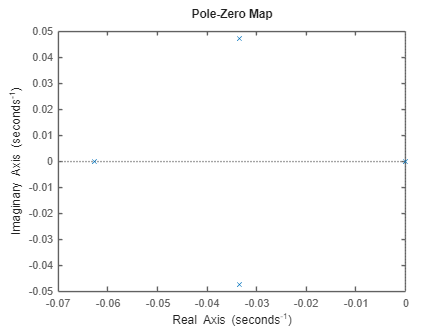

figure;
pzmap(sys_6K);

pz6=pzmap(sys_6K);

%Récupération des pôles
[poles_6, zeros_6] = pzmap(sys_6K);
disp('Pôles du système à 6 nœuds :');

Pôles du système à 6 nœuds :


disp(poles_6);

   0.0000 + 0.0000i
  -0.0335 + 0.0473i
  -0.0335 - 0.0473i
  -0.0627 + 0.0000i



Pour les deux systèmes, 3 des 4 pôles sont à valeurs réelles négatives, ce qui signifie que ce sont des pôles stables. Cependant les deux systèmes sont aussi composés d'un pôle de valeur nulle. Ce pôle à la limite de stabilité nous empêche de conclure sur la nature du système qui se trouve en limite de stabilité.

4) Pour pouvoir mieux décrire notre système on va s'intéresser aux valeurs de la pulsation propres et du facteur d'amortissement de chaque système:

Affichage des facteurs d'amortissements et pulsations propres liés aux pôles.

% Système pour 6 noeuds
[wn_6K,zeta_6K] = damp(sys_6K);
disp('Dampig ratio du système pour 6 noeuds');

Dampig ratio du système pour 6 noeuds


disp(zeta_6K);            % Affichage du facteur d'amortissement associés à nos pôles           

   -1.0000
    0.5778
    0.5778
    1.0000



disp('Natural frequency W du système pour 30 noeuds')

Natural frequency W du système pour 30 noeuds


disp(wn_6K);              % Affichage de la pulsation propres associés à nos pôles

         0
    0.0580
    0.0580
    0.0627



Le système se trouve donc en limite de stabilité à cause du pôle à valeur réellle nulle.

Par la suite nous avons simulé la réponse de notre ssytème à un signal échelon et une impulsion.

Réponse du système à un échelon

% Réponse des sytèmes à un échelon.
t=0:1:1000;
disp('Réponse du système à 6 noeuds pour un échelon')

Réponse du système à 6 noeuds pour un échelon


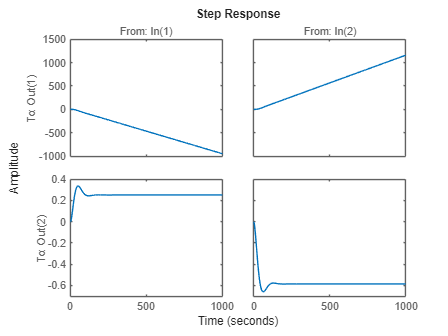

figure;
step(sys_6K,t); 


% Réponse des systèmes à des impulsions.
disp('Réponse du système à 6 noeuds pour une impulsion')

Réponse du système à 6 noeuds pour une impulsion


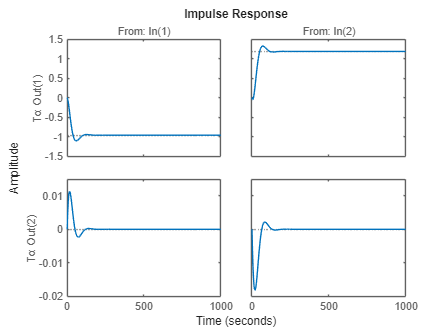

figure;
impulse(sys_6K,t); 

5) Les courbes précédentes mettent en évidence l'existence d'un couplage entre U1/S2 et U2/S1. Il est donc clair que des couplages sont présents dans ce système.

 ***Etude de sensibilité (partie 8)***

disp('Calcul de la sensibilité')

Calcul de la sensibilité


[V,D]=eig(A_6);
disp(cond(V))

   1.5307e+03



On remarque que la valeur de la plus grande singularité du système est très importante.

## 4) Objective's realisation.

Nous fixons un temps de réponse de 80 secondes pour la variation de *h* et de 100 secondes pour la variation de $\delta
$, tout en imposant un coefficient d'amortissement $\xi >0.65
$.

On suppose que les deux système H1 et H2 sont indépendants, chaque sous-système se voit associer deux valeurs propres : 

H1 :    $\lambda_1=-3/100 ; T_{r5\%}=100; \tau=\frac{T_{r5\%}}{3}; \lambda=-\frac{1}{\tau}$

        $\lambda_2=\frac{-3}{10}$ (car on souhaite que sa dynamique soit négligeable devant $\lambda_1
$)

H2 : $\lambda_3=-3/80 ; T_{r5\%}=80; \tau=\frac{T_{r5\%}}{3}; \lambda=-\frac{1}{\tau}$

        $\lambda_2=\frac{-3}{8}$ (car on souhaite que sa dynamique soit négligeable devant $\lambda_2$)

Déclaration des valeurs propres:

lambda1=-3/100;

lambda1 = -0.0300

lambda2=lambda1*10;

lambda2 = -0.3000

lambda3=-3/80;

lambda3 = -0.0375

lambda4=lambda3*10;

lambda4 = -0.3750

## 5) Eigenstructure assignment and decoupling.

On souhaite maintenant mettre en place une commande découplante permettant de rendre nos deux sous-systèmes \(H_1\) et \(H_2\) indépendants.  La forme de la matrice des vecteurs propres doit donc être de la forme suivante :   

Nous souhaitons avoir :

y=CVx  avec  C=[0 0 1 0; 0 0 0 1] 

On doit finalement avoir V de la forme V=[* * * *; * * * *; * * 0 0; 0 0 * *]

Méthode 1: 

On choisit les valeurs des * arbitrairement.

Méthode 2: 

Optimiser le choix des vecteurs propres, car nous avons deux lignes entièrement non spécifiées.   On tronque les lignes non spécifiées pour créer des vecteurs propres tronqués.

Dans la suite de ce BE nous avons choisis d'utiliser la seconde méthode.

Nlambda1=-inv(lambda1*eye(4)-A_6)*B_6;
Nlambda2=-inv(lambda2*eye(4)-A_6)*B_6;
Nlambda3=-inv(lambda3*eye(4)-A_6)*B_6;
Nlambda4=-inv(lambda4*eye(4)-A_6)*B_6;

Nlambda1_t=Nlambda1(3:end,:);
Nlambda2_t=Nlambda2(3:end,:);
Nlambda3_t=Nlambda3(3:end,:);
Nlambda4_t=Nlambda4(3:end,:);


% valeurs propres tronquées 
vp1_t=[0;1];
vp2_t=[0;2];
vp3_t=[1;0];
vp4_t=[2;0];

z1=Nlambda1_t'*inv(Nlambda1_t*Nlambda1_t')*vp1_t;
z2=Nlambda2_t'*inv(Nlambda2_t*Nlambda2_t')*vp2_t;
z3=Nlambda3_t'*inv(Nlambda3_t*Nlambda3_t')*vp3_t;
z4=Nlambda4_t'*inv(Nlambda4_t*Nlambda4_t')*vp4_t;

% z1=inv(transpose(Nlambda1_t)*Nlambda1_t)*transpose(Nlambda1_t)*vp1_t;
% z2=inv(transpose(Nlambda2_t)*Nlambda2_t)*transpose(Nlambda2_t)*vp2_t;
% z3=inv(transpose(Nlambda3_t)*Nlambda3_t)*transpose(Nlambda3_t)*vp3_t;
% z4=inv(transpose(Nlambda4_t)*Nlambda4_t)*transpose(Nlambda4_t)*vp4_t;

% Calcul des vecteurs propres non tronqués
vp1=Nlambda1*z1;
vp2=Nlambda2*z2;
vp3=Nlambda3*z3;
vp4=Nlambda4*z4;
V=[vp1 vp2 vp3 vp4];

% On détermine les zi entiers


Comme M=eye(4), les wi=zi

w1=z1;
w2=z2;
w3=z3;
w4=z4;
W=[w1 w2 w3 w4];

Calcul du gain pour le retour d'état découplé

K=W*inv(V);


Test avec le système corrigé

Nous avons bien les valeurs propres correctes lorsque l'on regarde les valeurs propres de la boucle fermée.

disp('Les valeurs propres du systèmes corrigé sont:')

Les valeurs propres du systèmes corrigé sont:


disp(eig(A_6-B_6*K))

   -0.3750
   -0.0375
   -0.3000
   -0.0300



On doit maintenant contraindre la matrice H afin d'avoir l'indépendance des modes de commande. On doit donc avoir u*B*H=[0 *; 0 *; * 0; * 0]

On trouve alors des contraintes entre h1, h3 et h2, h4 valeurs de la matrice H.

On a alors : h1=-b/a * h3   et h2=-f/e *h4

temp=inv(V)*B_6;
a=temp(1,1);
b=temp(1,2);
c=temp(2,1);
d=temp(2,2);
e=temp(3,1);
f=temp(3,2);
g=temp(4,1);
h=temp(4,2);

h3=-1/2.31; 
h4=-1/0.8;
h1=-b/a*h3;
h2=-f/e*h4;
H=[h1 h2; h3 h4];


Définition du système corrigé.

Acorr=A_6-B_6*K;
Bcorr=B_6*H;
Ccorr=C_6;
Dcorr=zeros(2,2)

Dcorr =      0     0
     0     0



% Réponse des sytèmes à un échelon.
t=0:1:1000;
sys_corr=ss(Acorr,Bcorr,Ccorr,Dcorr);
disp('Réponse du système corrigé à 6 noeuds pour un échelon')

Réponse du système corrigé à 6 noeuds pour un échelon


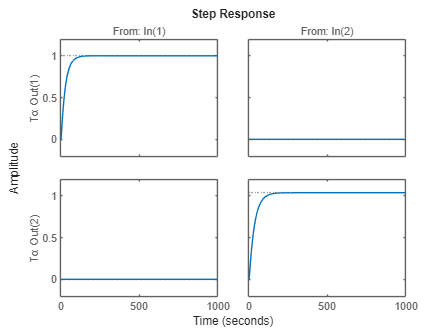

figure;
step(sys_corr,t); 

Nous remarquons que nous obtenons bien un système découplé, les sorties ne dépendent que d'une entrée.

Pour déterminer le gain unitaire de H, nous avons simulé le système avec le gain H déterminé dès le début et avons observé la valeur du gain statique.

disp('Calcul de la sensibilité')

Calcul de la sensibilité


[V,D]=eig(Acorr);
disp(cond(V))

   27.1246



On remarque que la valeur de la plus grande singularité du système est amélioré par rapport au système en boucle ouverte (non régulé).

***Partie 6:***

disp('########################################################################## \n')

########################################################################## \n


disp('Partie 6')

Partie 6



$$\[
Y_c = CX
\]
Démontrons qu'un tel découplage peut être obtenu en choisissant :
\[
H = \Omega_{22} + K\Omega_{12}
\]

En reprenant les équations initiales, nous avons :
\[
\dot{X} = AX + BU
\]

En substituant $U$ dans l'équation de $\dot{X}$ :
\[
\dot{X} = AX - BKX + B H Y_c.
\]

Pour garantir que $Y_c = CX$, il suffit d'imposer :
\[
(-\Omega_{22} - K\Omega_{12}) Y_c = (-B^{-1}A + K)X,
\]
et donc
\[
Y_c = CX,
\]
en validant les relations entre $\Omega$ et les matrices système.

Ainsi, en choisissant $H = \Omega_{22} + K\Omega_{12}$, le découplage statique est assuré.$$


Déclaration des Omegas: 

temp=inv([A_6,B_6; C_6,D_6]);
W11=temp(1:4,1:4);
W12=temp(1:4,5:end);
W21=temp(3:end,1:2);
W22=temp(5:end,5:end);

H=W22 + K*W12;

Acorr=A_6-B_6*K;
Bcorr=B_6*H;
Ccorr=C_6;
Dcorr=zeros(2,2);

% Réponse des sytèmes à un échelon.
t=0:1:1000;
sys_corr=ss(Acorr,Bcorr,Ccorr,Dcorr);
disp('Réponse du système corrigé à 6 noeuds pour un échelon')

Réponse du système corrigé à 6 noeuds pour un échelon


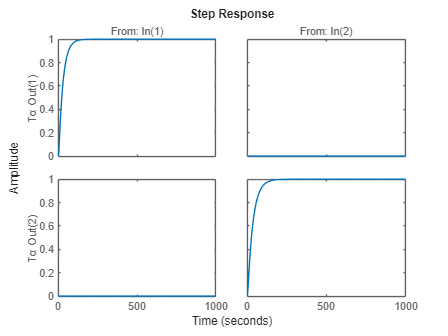

figure;
step(sys_corr,t); 

Nous pouvons observer que ce gain H de découplage en mode statique nous permet bien d'obtenir une commande découplée avec un gain statique égal à 1. Le découplage est lui toujours bien respecté.

***Partie 7: Placement des pôles insensibles.***

disp('########################################################################## \n')

########################################################################## \n


disp('Partie 7')

Partie 7


1) La fonction place.m permet de déterminer le gain permettant de placer les pôles de notre système tout en ayant les pôles les plus robustes aux variations des paramètres du système. 

2) Placement des pôles avec une sensibilité minimale.

disp('Placement des pôles avec une sensibilité minimale')

Placement des pôles avec une sensibilité minimale



K2=place(A_6,B_6,poles_6);

H2=W22 + K2*W12;

Acorr2=A_6-B_6*K2;
Bcorr2=B_6*H2;
Ccorr2=C_6;
Dcorr2=zeros(2,2);

% Réponse des sytèmes à un échelon.
t=0:1:1000;
sys_corr2=ss(Acorr2,Bcorr2,Ccorr2,Dcorr2);
disp('Réponse du système corrigé avec des pôles robustes pour un échelon')

Réponse du système corrigé avec des pôles robustes pour un échelon


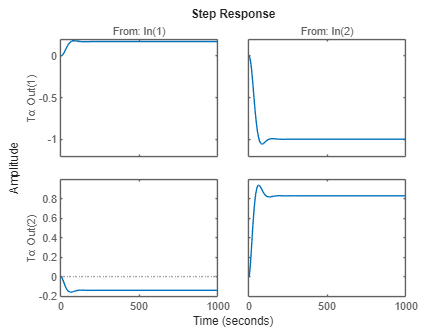

figure;
step(sys_corr2,t); 

3) On remarque que lorsque l'on met en place la correction avec le placement de poles le plus robuste ne permet pas d'obtenir des résultats convenables pour le découplage.

disp('Calcul de la sensibilité')

Calcul de la sensibilité


[V,D]=eig(Acorr2);
disp(cond(V))

  120.5962



On remarque que ce placement de pôle n'est pas le plus "insensible", la valeur de la singularité est intermédiaire ce qui est étonnant étant donné que place doit être le placement le plus "insensible".

***Partie 8:***

1) La fonction cond.m permet de déterminer le conditionnement de la matrice modale Ac, cette fonction renvoie un ratio dépendant de la plus grande singularité de A nous permettant que quantifier le risque d'instabilité du calcul d'inversion.

(On va donc étudier le risque d'instabilité des systèmes définis précédemment. Voir au dessus)

Les résultats obetnus sont étranges, place aurait du nous donner quelque chose de moins sensible, ensuite quand on retire une commande on devrait devenir plus sensible car plus dur de rattraper si on a un moteur sur 2.

Fonctionnement en mode dégradé (U1 inactif) :

K2=place(A_6,B_6,poles_6);

H2=W22 + K2*W12;

Acorr2=A_6-B_6*K2;
Bcorr2=B_6*H2;
Ccorr2=C_6;
Dcorr2=zeros(2,2);

disp('Calcul de la sensibilité')

Calcul de la sensibilité


[V,D]=eig(Acorr2);
disp(cond(V))

  120.5962




% Réponse des sytèmes à un échelon.
t=0:1:1000;
sys_corr2=ss(Acorr2,Bcorr2,Ccorr2,Dcorr2);
disp('Réponse du système corrigé dégradé par U1 inactif pour un échelon')

Réponse du système corrigé dégradé par U1 inactif pour un échelon


figure;
step(sys_corr2,t); 

Fonctionnement en mode dégradé (U2 inactif) :

K2=place(A_6,B_6,poles_6);

H2=W22 + K2*W12;

Acorr2=A_6-B_6*K2;
Bcorr2=B_6*H2;
Ccorr2=C_6;
Dcorr2=zeros(2,2);

disp('Calcul de la sensibilité')

Calcul de la sensibilité


[V,D]=eig(Acorr2);
disp(cond(V))

  120.5962




% Réponse des sytèmes à un échelon.
t=0:1:1000;
sys_corr2=ss(Acorr2,Bcorr2,Ccorr2,Dcorr2);
disp('Réponse du système corrigé dégradé par U2 inactif pour un échelon')

Réponse du système corrigé dégradé par U2 inactif pour un échelon


figure;
step(sys_corr2,t); 